# GNB School 2023 - “The Bioengineering of Sport” 

# *Signal processing and feature extraction in sport:  the case of in-field running*

In the biomechanical analysis of running technique, one of the principal components is the determination of footstrike patterns (i.e., the way the foot touches the ground). As  shown in figure below, depending on the part of the foot that is first in contact with the ground, the pattern is commonly described with three primary types: rearfoot strike  (RFS, A), midfoot strike (MFS, B), and forefoot strike (FFS, C). 

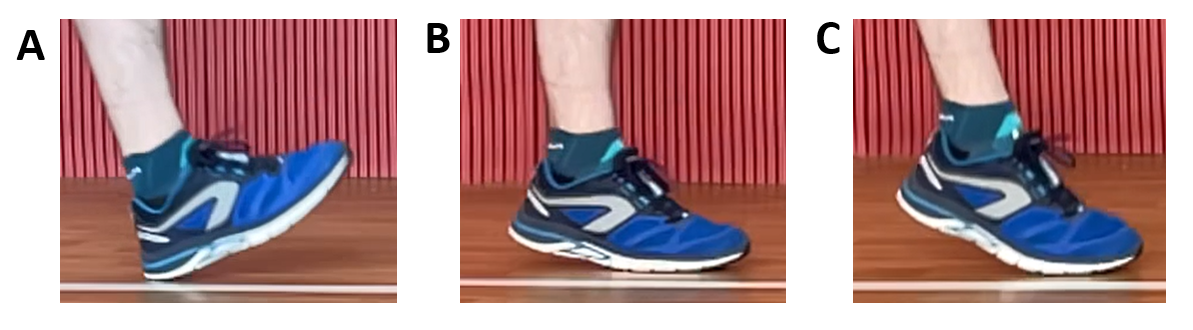

Three participants run on a treadmill at 3.5 m/s with their abitual footfall pattern. Five IMUs were attached to head, pelvis, tibia, heel and V metatarsal head, as shown in figure below (only data of right lower limb was recorded). The table on the right of the figure describe the axes alignment for each IMU. Data for each subject were stored in .mat files (AthleteA, AthleteB, AthleteC).

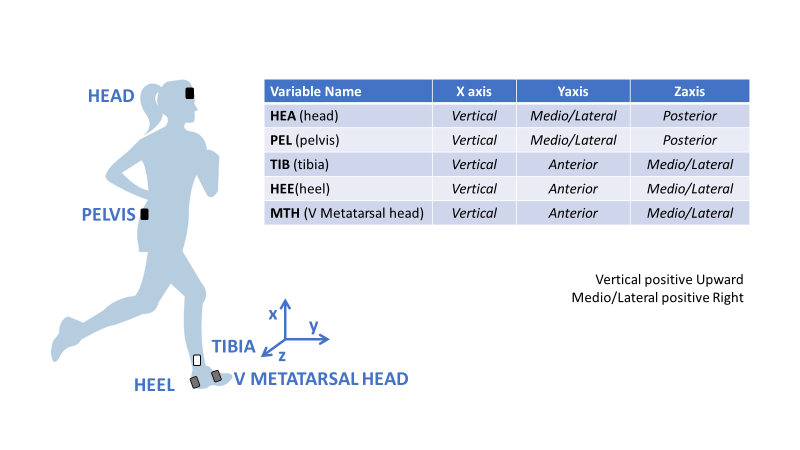

## B. Data loading and visualization

#### *B.1. - Loading *.mat file*

clear, close all
[file,path] = uigetfile('*.mat');
eval (['load ',file])

#### *B.2. - Raw data visualization*

Vertical linear acceleration (m/s^2) and mediolateral angular velocity (rad/s)

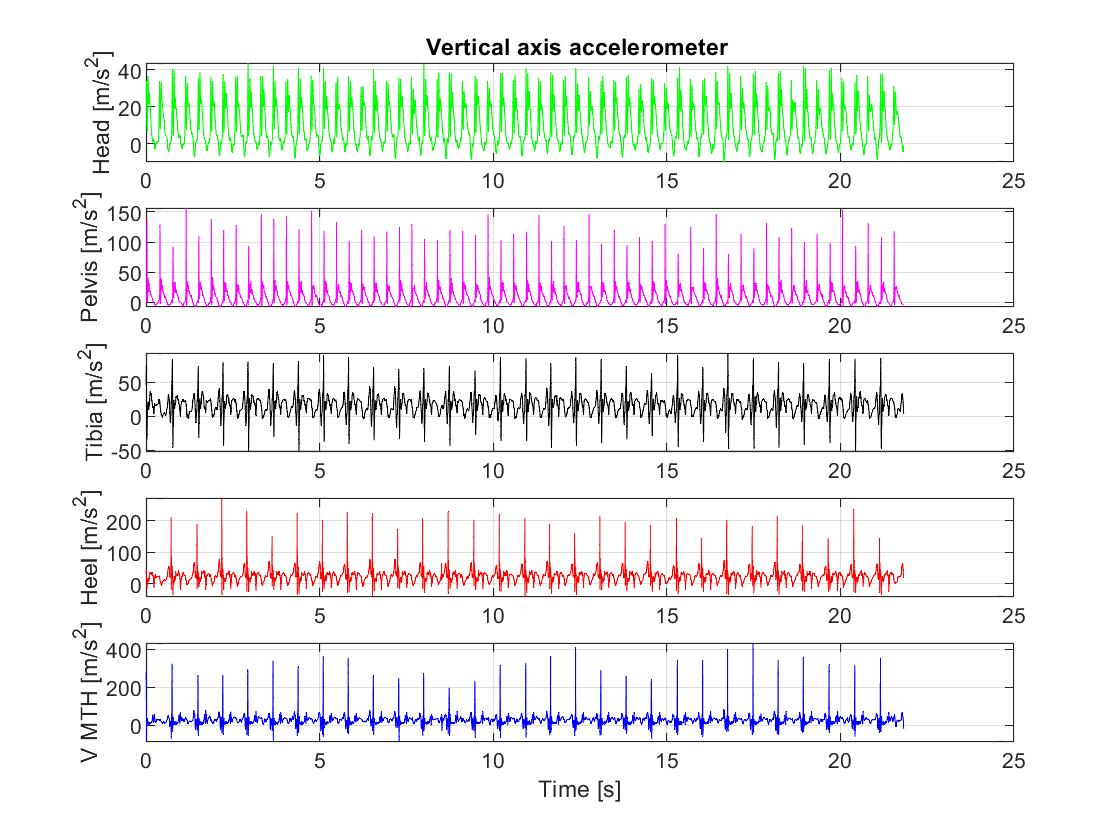

Nframe=length(PEL.acc(:,1));
time=[1:Nframe]/Fs;

figure
ax1= subplot(5,1,1);
    plot(time,HEA.acc(:,1),'g'), grid on
    hold on
    ylabel('Head [m/s^2]')
    title('Vertical axis accelerometer ')
ax2 = subplot(5,1,2);
    plot(time,PEL.acc(:,1),'m'), grid on
    ylabel('Pelvis [m/s^2]')
ax3 = subplot(5,1,3);
    plot(time,TIB.acc(:,1),'black'), grid on
    ylabel('Tibia [m/s^2]')
ax4= subplot(5,1,4);
    plot(time,HEE.acc(:,1),'r'), grid on
    ylabel('Heel [m/s^2]')
ax5 = subplot(5,1,5);
    plot(time,MTH.acc(:,1),'b'), grid on
    ylabel('V MTH [m/s^2]')
    xlabel('Time [s]')

linkaxes([ax1 ax2 ax3 ax4 ax5],'x')

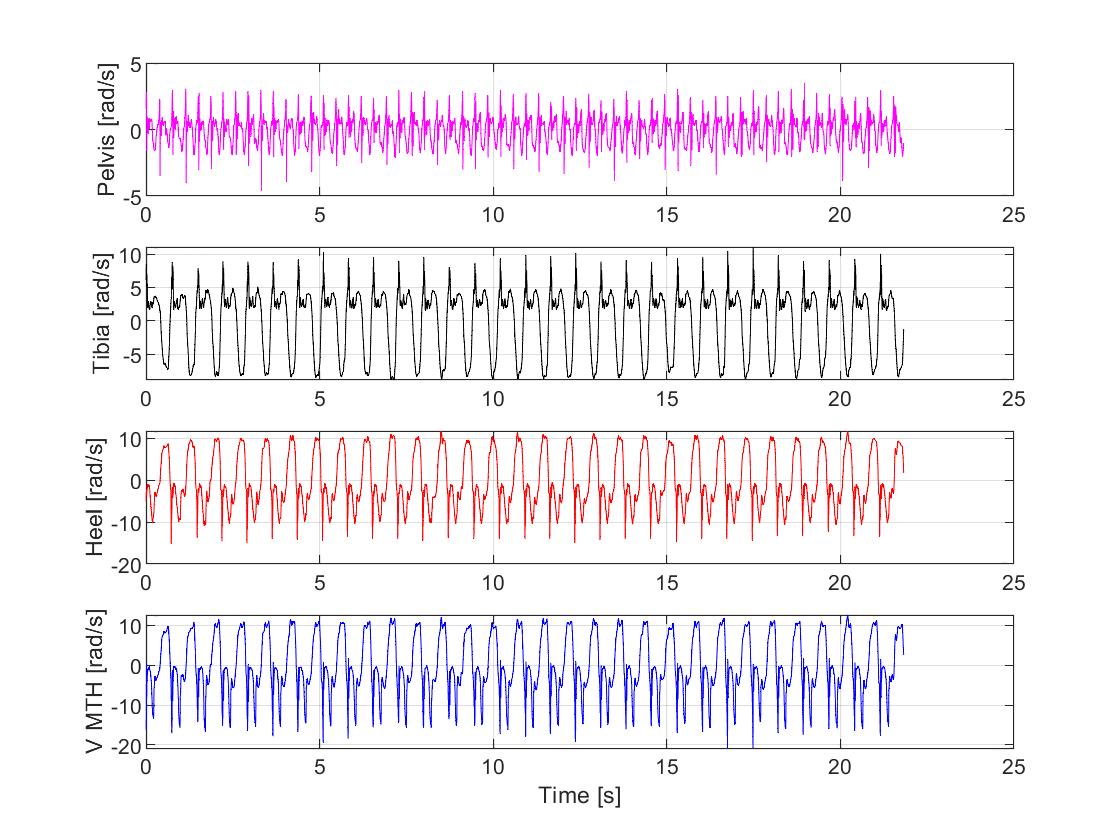

figure

ax2 = subplot(4,1,1);
    plot(time,PEL.gyr(:,2),'m'), grid on
    ylabel('Pelvis [rad/s]')
ax3 = subplot(4,1,2);
    plot(time,TIB.gyr(:,3),'black'), grid on
    ylabel('Tibia [rad/s]')
ax4= subplot(4,1,3);
    plot(time,HEE.gyr(:,3),'r'), grid on
    ylabel('Heel [rad/s]')
ax5 = subplot(4,1,4);
    plot(time,MTH.gyr(:,3),'b'), grid on
    ylabel('V MTH [rad/s]')
    xlabel('Time [s]')

linkaxes([ax2 ax3 ax4 ax5],'x')

## C. Foot Strike Classification

#### *C.1. - From raw signal of foot acceleration Heel and Fifth Metatarsal Head*

Using the approach of Giandolini (2014) using the value of THM FFS < 5.49 ms< MFS < 15.2 ms < RFS is it possible to identify the type of the foot strike pattern of the athlete under investigation.

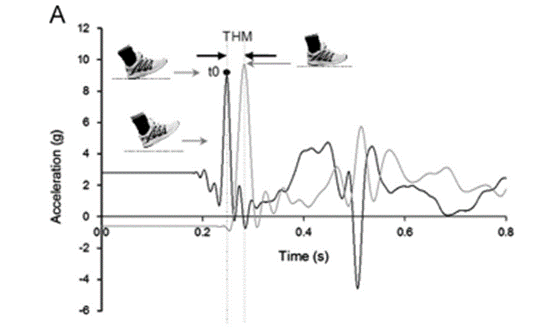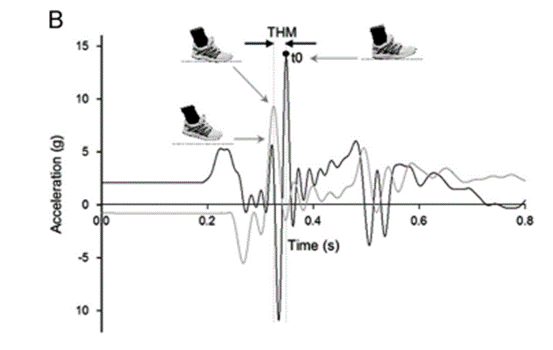

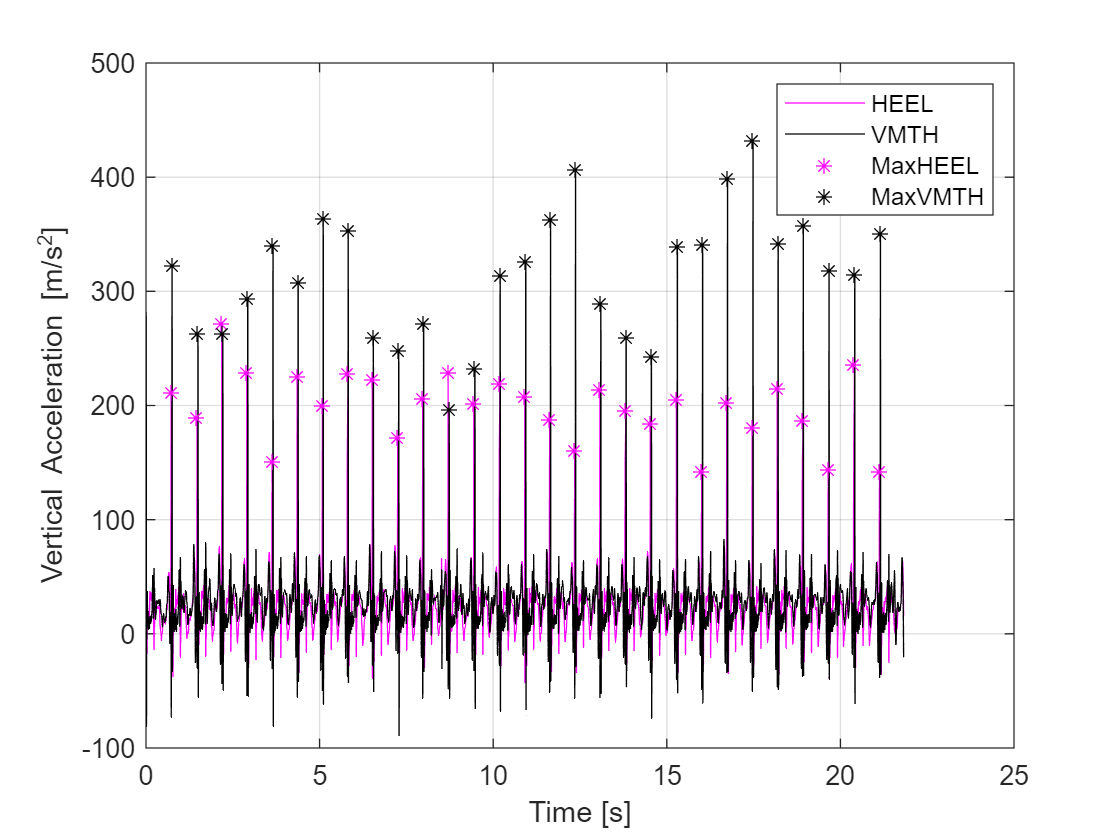

[Max_Heel,locs_MH]=findpeaks(HEE.acc(:,1),Fs,'MinPeakHeight',80,'MinPeakDistance',0.5);
[Max_VMTH,locs_VM]=findpeaks(MTH.acc(:,1),Fs,'MinPeakProminence',200,'MinPeakDistance',0.5);


figure
    plot(time,HEE.acc(:,1),'m'), grid on, hold on
    plot(time,MTH.acc(:,1),'k')
    plot(locs_MH,Max_Heel,'m*')
    plot(locs_VM,Max_VMTH,'k*')
    legend('HEEL','VMTH','MaxHEEL','MaxVMTH')
    ylabel('Vertical Acceleration [m/s^2]')
    xlabel('Time [s]')

#### *C.2. - Impact Attenuation (time-domain)*

First the segmentation of gait cycle from the mediolateral angular velocity of tibia sensor for the foot off and from the acceleration of the two sensor on the foot for foot contact was performed.

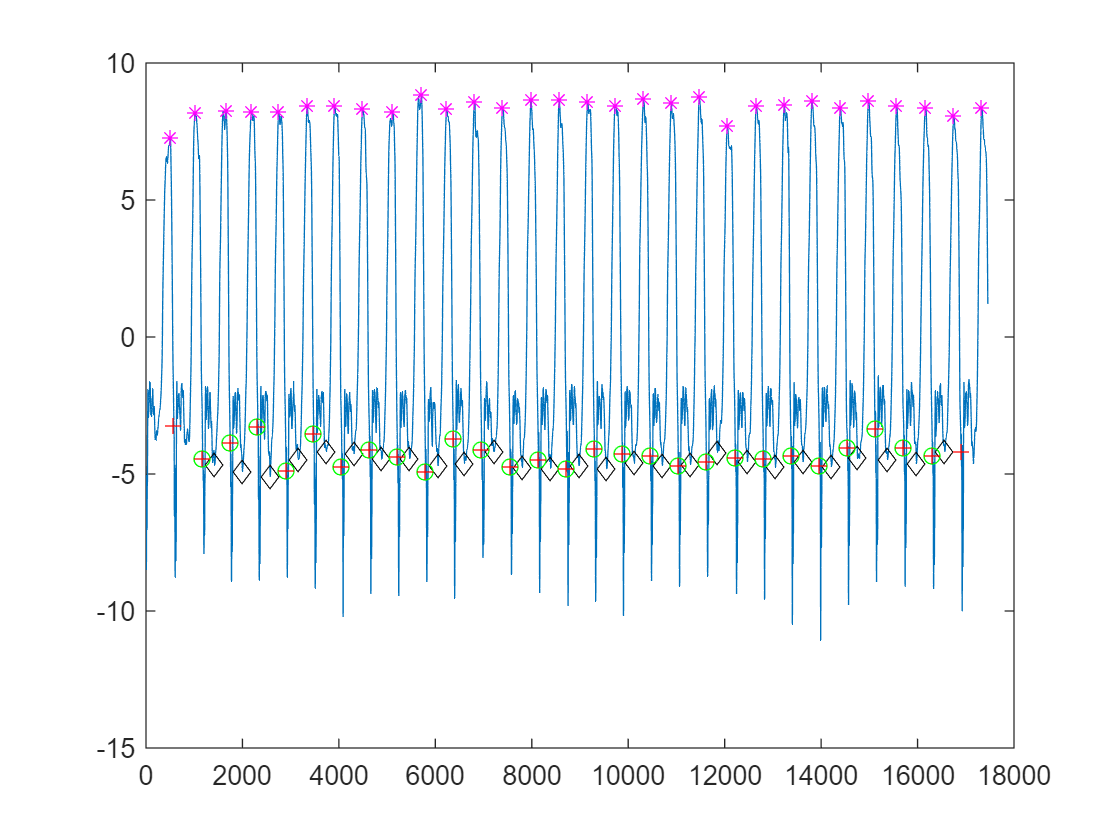

[peak, T_peak] = findpeaks(-TIB.gyr(:,3),'MinPeakDistance',Fs/1.6);

N_stride=length(locs_MH);
for j=1:N_stride
Foot_Contact_foot(j)=round(min([locs_MH(j) locs_VM(j)])*Fs);%taking into account different type of foot strike
end
k=1;
for i=2:length(T_peak)-2
    interval=T_peak(i+1)-T_peak(i);
    half_interval=round(interval/2);
    [FO(k) index_FO]=min(-TIB.gyr(T_peak(i)+half_interval:T_peak(i+1),3));
    for j=1:N_stride %selection of the foot contact within the stride cycle 
       if Foot_Contact_foot(j)<T_peak(i+1) && Foot_Contact_foot(j)>T_peak(i)
           Foot_Contact(k)=Foot_Contact_foot(j);
       end
    end
    Foot_Off(k)=round(T_peak(i)+half_interval+index_FO);
    k=k+1;
    i=i+1;
end

stride_cycle=round(mean(Foot_Contact(2:end)-Foot_Contact(1:end-1)));

%representation on mediolateral angular velocity of the tibia
figure
plot(-TIB.gyr(:,3))
hold on
plot(T_peak,-TIB.gyr(T_peak,3),'m*')
plot(Foot_Off,-TIB.gyr(Foot_Off,3),'kd')
plot(Foot_Contact,-TIB.gyr(Foot_Contact,3),'go')
plot(Foot_Contact_foot,-TIB.gyr(Foot_Contact_foot,3),'r+')

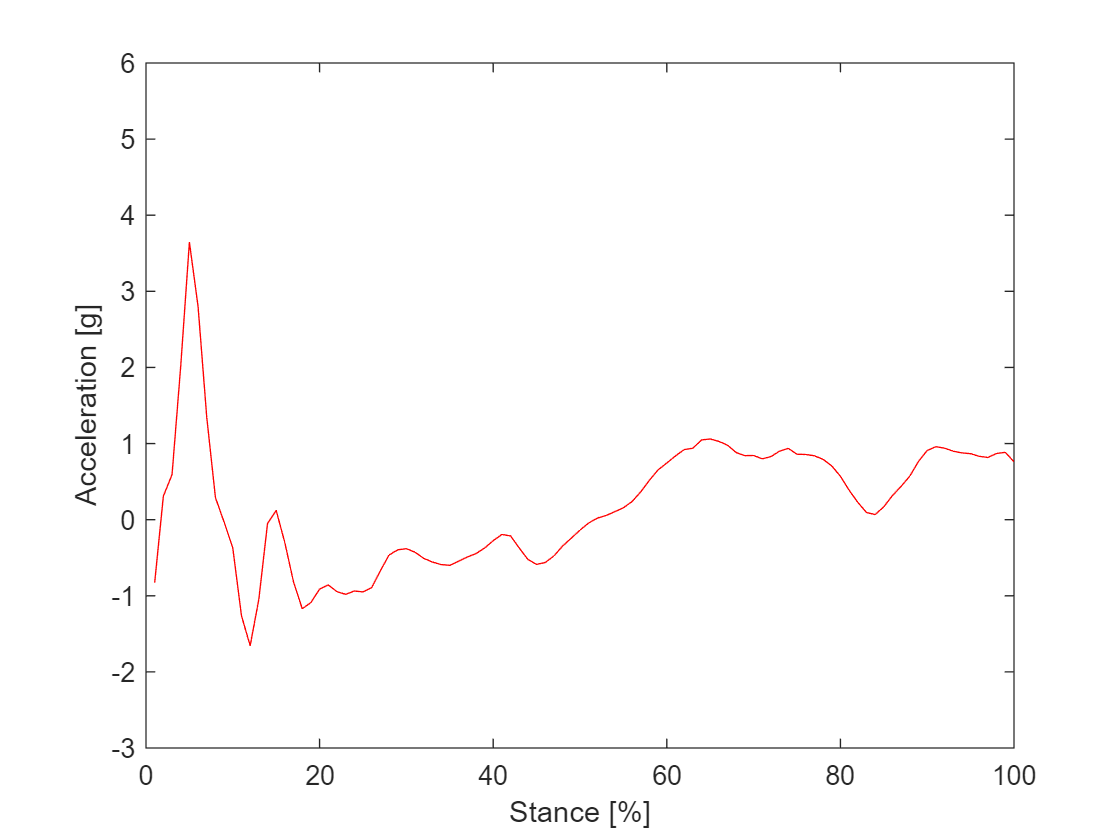

%% Detrend of the signal for deleting the gravity and expressed in g as typical for shock attenuation analysis
g=9.81;

TIBIA_det=detrend(TIB.acc(:,3))./g;
HEAD_det=detrend(HEA.acc(:,3))./g;

%estimation of the mean patterns for tibia acceleration during stance
%considering 100 sample for stance phase

for i=1:length(Foot_Contact)
   TIBIA_stance(i,1:100)=interpft(TIBIA_det(Foot_Contact(i):Foot_Off(i),1),100);
end

TIBIA_Mean=mean(TIBIA_stance);

figure

plot(TIBIA_Mean,'r')
hold on
ylabel('Acceleration [g]')
xlabel('Stance [%]')
axis([0 100 -3 6])

#### *C.2. - Shock Attenuation (frequency-domain)*

Schematic diagram of steps in the determination of power spectral densities of accelerometer data (Shotren & Winslow 1992).

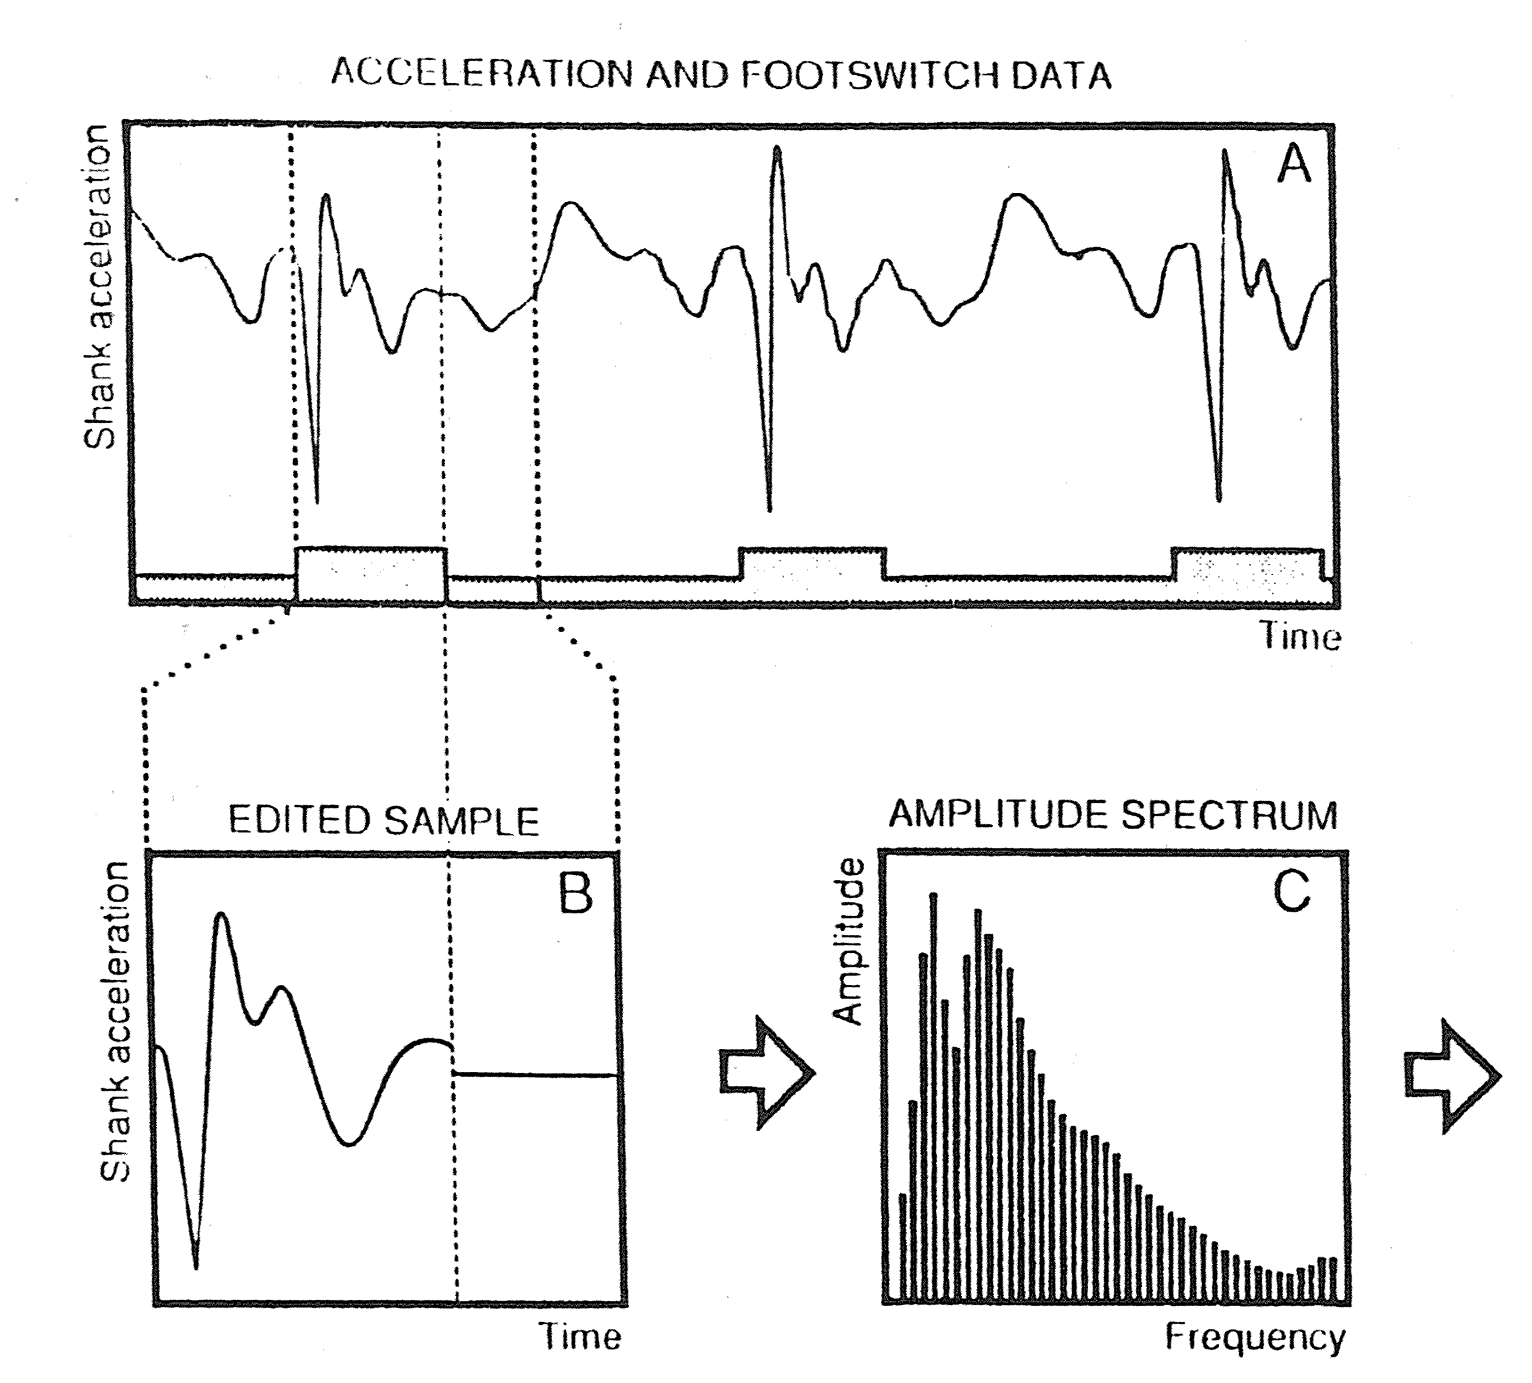

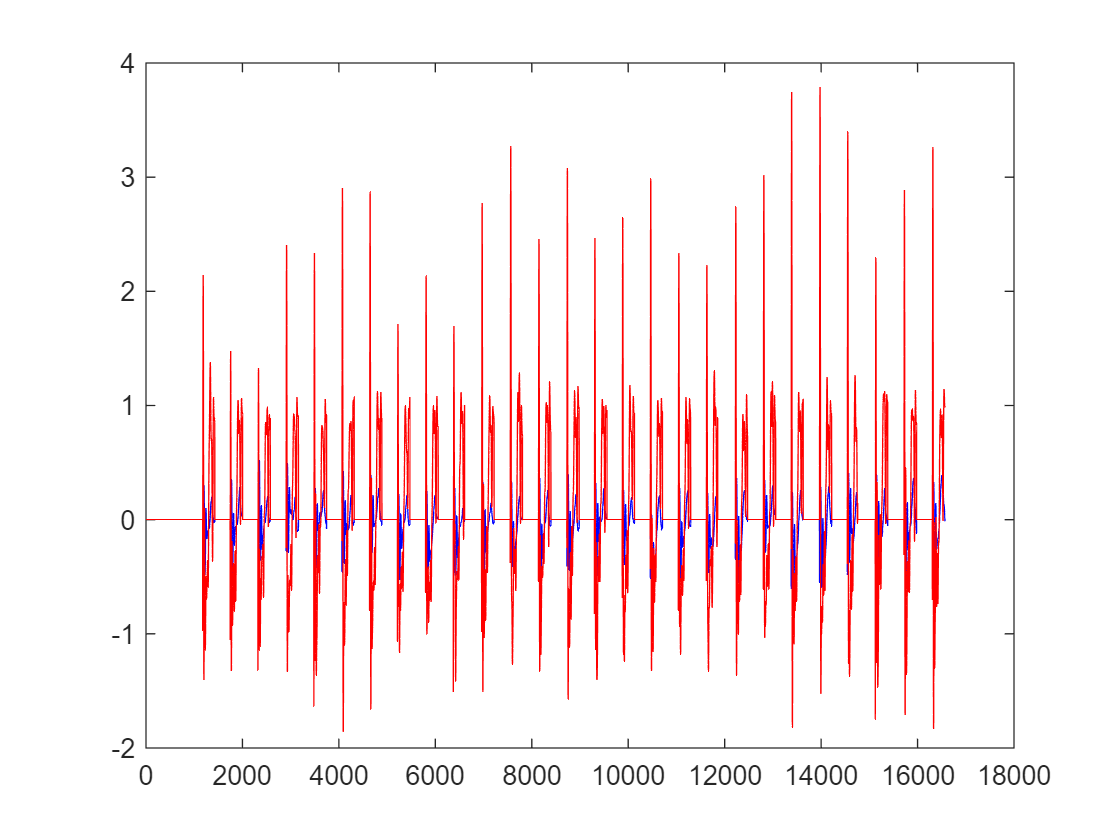

Fc=40;  % Filtering the signal with Cut Frequency of 40Hz
[b,a] = butter(4,Fc/(Fs/2),'low');           
TIBIA_detf = filtfilt(b,a,TIBIA_det); 
HEAD_detf = filtfilt(b,a,HEAD_det);

%Deleting the swing phase, forcing zero values for relevant frame
TIBIA_zero=zeros(Nframe,1);
HEAD_zero=zeros(Nframe,1);
for i=1:length(Foot_Contact)
  TIBIA_zerof(Foot_Contact(i):Foot_Off(i))=TIBIA_detf(Foot_Contact(i):Foot_Off(i));%%%modificato metto il filtro prima dopo non aveva senso
  HEAD_zerof(Foot_Contact(i):Foot_Off(i))=HEAD_detf(Foot_Contact(i):Foot_Off(i));
end


figure
plot(HEAD_zerof,'b')
hold on
plot(TIBIA_zerof,'r')

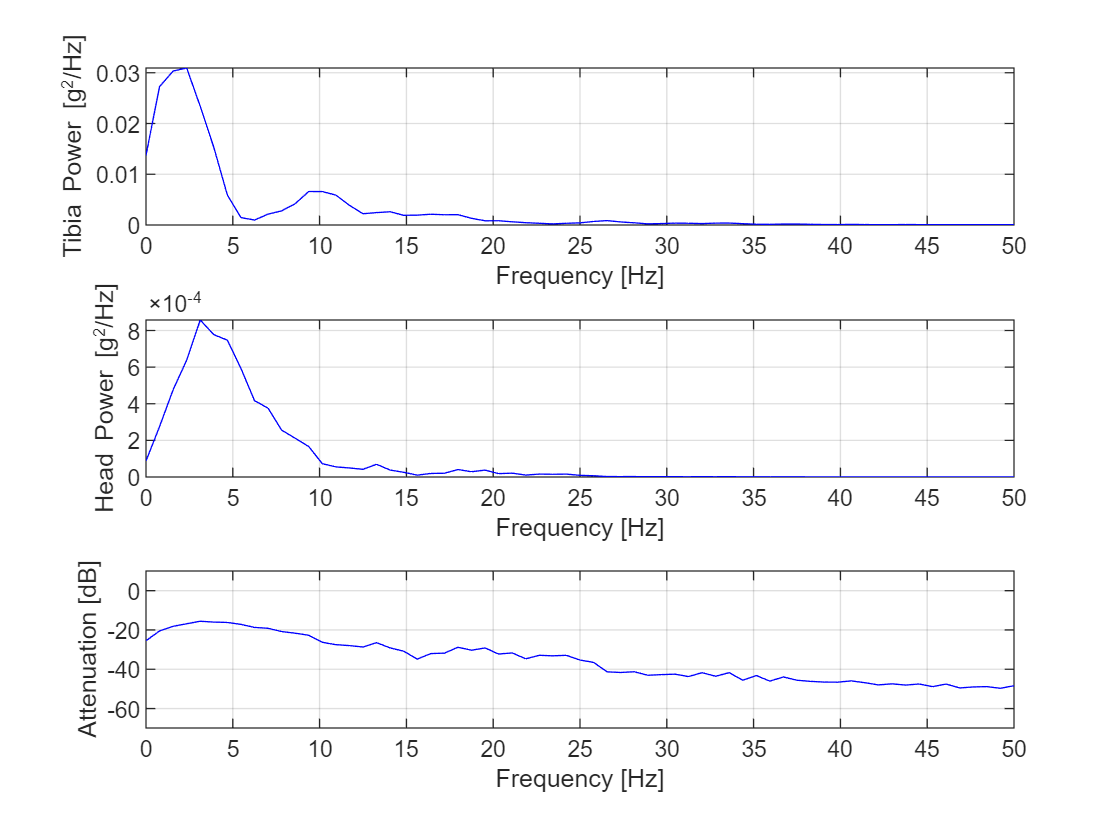



n_dx = 2^nextpow2(stride_cycle);

[Power_tibia, Frequency_tibia] = pwelch(TIBIA_zerof, stride_cycle, 0, n_dx, Fs);
[Power_head, Frequency_head] = pwelch(HEAD_zerof, stride_cycle, 0, n_dx, Fs);
%transfer function positive gain, negative attenuation
TF=10*log10(Power_head/Power_tibia);

figure
subplot(311)
plot(Frequency_tibia,Power_tibia,'b'), hold on, grid on, 
ylabel('Tibia Power [g^2/Hz]')
xlabel('Frequency [Hz]')
axis([0 50 0 Inf])
subplot(312)
plot(Frequency_head,Power_head,'b'), hold on, grid on, 
ylabel('Head Power [g^2/Hz]')
xlabel('Frequency [Hz]')
axis([0 50 0 Inf])
subplot(313)
plot(Frequency_tibia,TF,'b'), hold on, grid on, 
ylabel('Attenuation [dB]')
xlabel('Frequency [Hz]')
axis([0 50 -inf 10])